# Star Secular Determinant

Computes analytical and numerical secular determinants and compares the results with each other as well as the squareroots of the eigenvalues.

### Create the graph

Creates the graph with both the uniform and Chebyshev discretizations so we can compare the eigenvalues of these two discretizations later

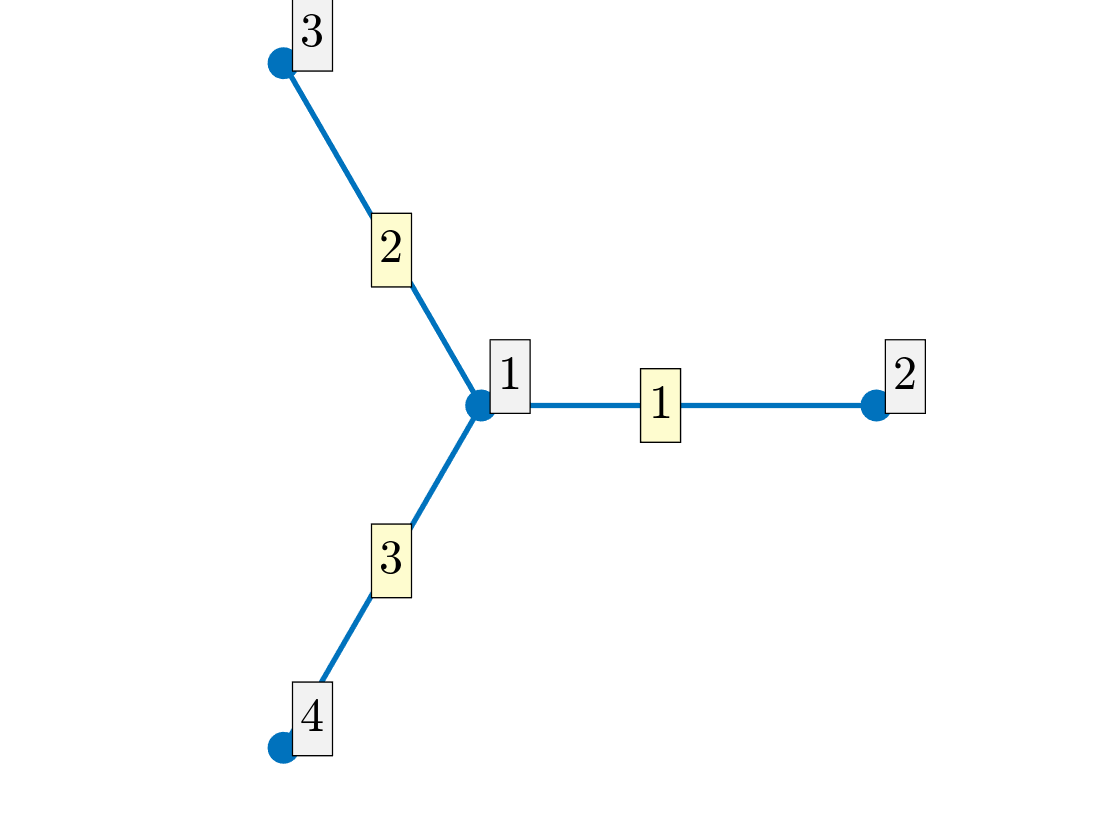

syms k
clf;
alpha = 1;
robinCoeff = [0 alpha alpha alpha];
Phi = quantumGraphFromTemplate('star','robinCoeff',robinCoeff,'discretization','Chebyshev','nx',16);
PhiU = quantumGraphFromTemplate('star','robinCoeff',robinCoeff,'discretization','Uniform','nx',64);
Phi.plot('layout')

## Numerical Secular Determinant

This converts the symbolic numerical secular determinant to a Matlab function then plots it and it's zeros

[SD,S,D] = Phi.secularDet;
disp('The numerical secular determinant is:')

The numerical secular determinant is:


disp(SD)

$$\begin{array}{l} \frac{x\,\sin\left(\pi \,x\right)-3\,x^{2}\,\sigma_{1}-\cos\left(\pi \,x\right)+2\,x^{2}\,\cos\left(\pi \,x\right)+\sigma_{1}-3\,x\,\sigma_{2}\,\sin\left(\pi \,x\right)+x^{3}\,\sigma_{2}\,\sin\left(\pi \,x\right)}{{\left(x^{2}+1\right)}^{3/2}}\\ \mathrm{where}\\ \sigma_{1}={\cos\left(\pi \,x\right)}^{3}\\ \sigma_{2}={\cos\left(\pi \,x\right)}^{2} \end{array}$$

(I should point out that this S matrix matches my analytic results.)

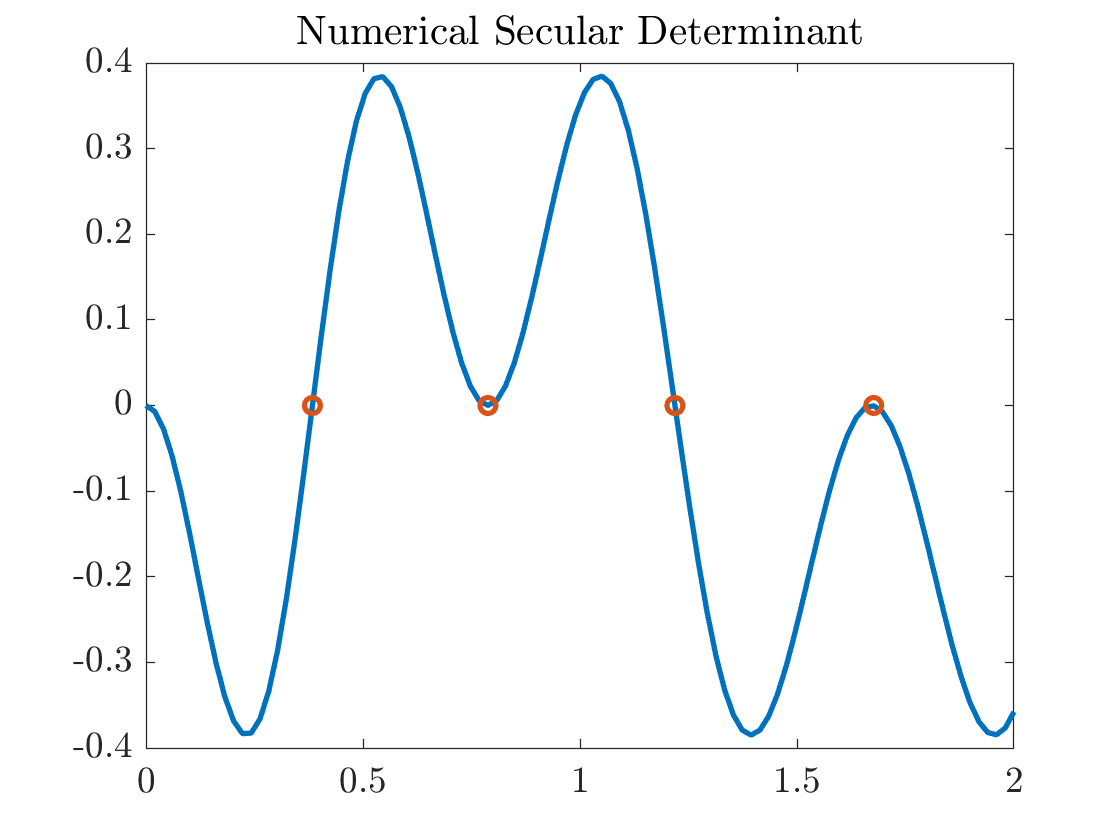

F=matlabFunction(SD);
x=linspace(0,2);
Fx=F(x);
clf
plot(x,Fx) 
title('Numerical Secular Determinant')

% Finds zeros of F(x)
kmax=2;
signChanges=find(Fx(1:end-1).*Fx(2:end)<0);
nSignChanges=length(signChanges);
kstar=zeros(nSignChanges,1);
for n=1:nSignChanges
    kstar(n)=fzero(F,x(signChanges(n)+[0 1]));
end
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=zeros(2,1);
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-3)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
kstar = union(kstar,doubleRoots);
hold on
plot(kstar,zeros(size(kstar)),'o')

lambdaNumerical = kstar.^2;

## Analytical Secular Determinant

This converts the symbolic analytical secular determinant to a Matlab function then plots it and it's zeros

analyticSD = (-alpha*cos(k*pi)+k*sin(k*pi))*(alpha*k*cos(k*pi)+sin(k*pi))^2;
disp('The analytic secular determinant is:')

The analytic secular determinant is:


disp(analyticSD)

$$-{\left(\sin\left(\pi \,k\right)+k\,\cos\left(\pi \,k\right)\right)}^{2}\,\left(\cos\left(\pi \,k\right)-k\,\sin\left(\pi \,k\right)\right)$$

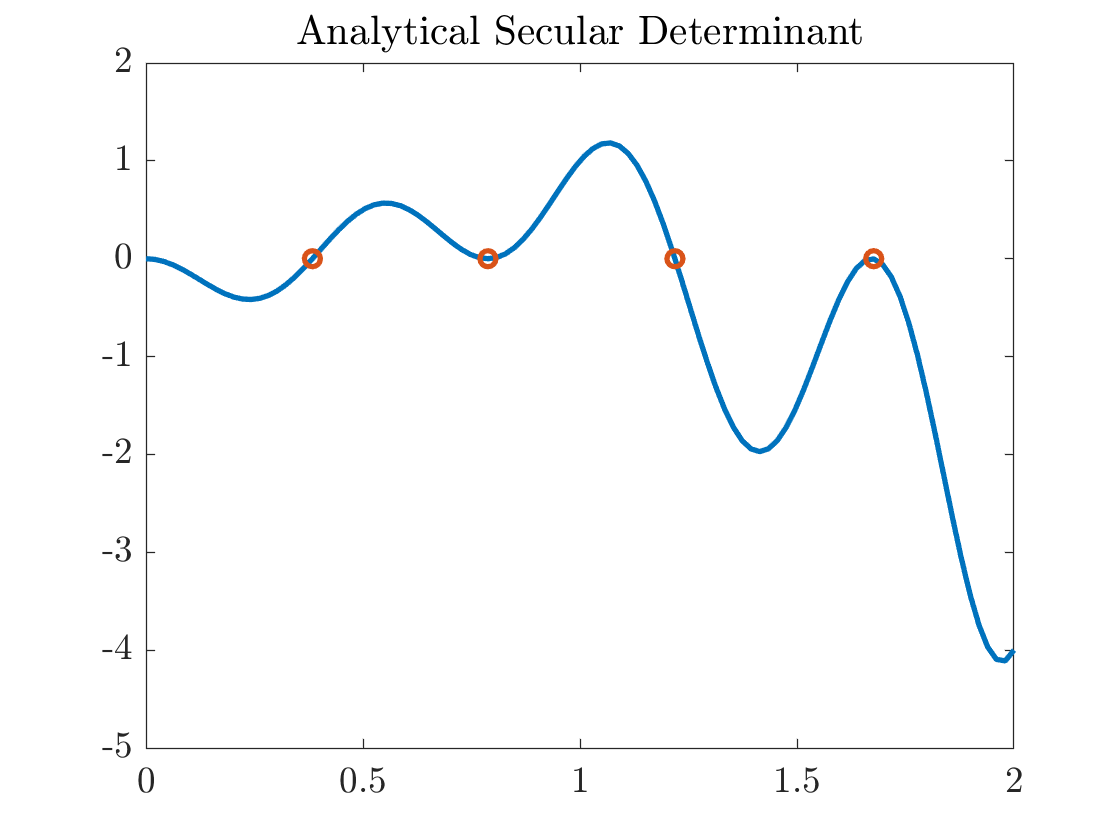

analyticF = matlabFunction(analyticSD);
analyticFx = analyticF(x);
figure
plot(x,analyticFx)
title('Analytical Secular Determinant')

% Finds zeros of F(x)
signChangesA=find(analyticFx(1:end-1).*analyticFx(2:end)<0);
nSignChangesA=length(signChangesA);
kstarA=zeros(nSignChangesA,1);
for n=1:nSignChangesA
    kstarA(n)=fzero(analyticF,x(signChangesA(n)+[0 1]));
end
min=islocalmin(Fx); min = find(min==1);
max=islocalmax(Fx); max = find(max==1);
minmax=union(min,max);
i=1;
doubleRoots=zeros(2,1);
for n=1:length(minmax)
    if abs(F(x(minmax(n))))<10^(-3)
        doubleRoots(i)=x(minmax(n));
        i=i+1;
    end
end
kstarA = union(kstarA,doubleRoots);
hold on
plot(kstarA,zeros(size(kstarA)),'o')

lambdaAnalytic = kstarA.^2;

We then create a plot comparing the two secular determinants and their roots.

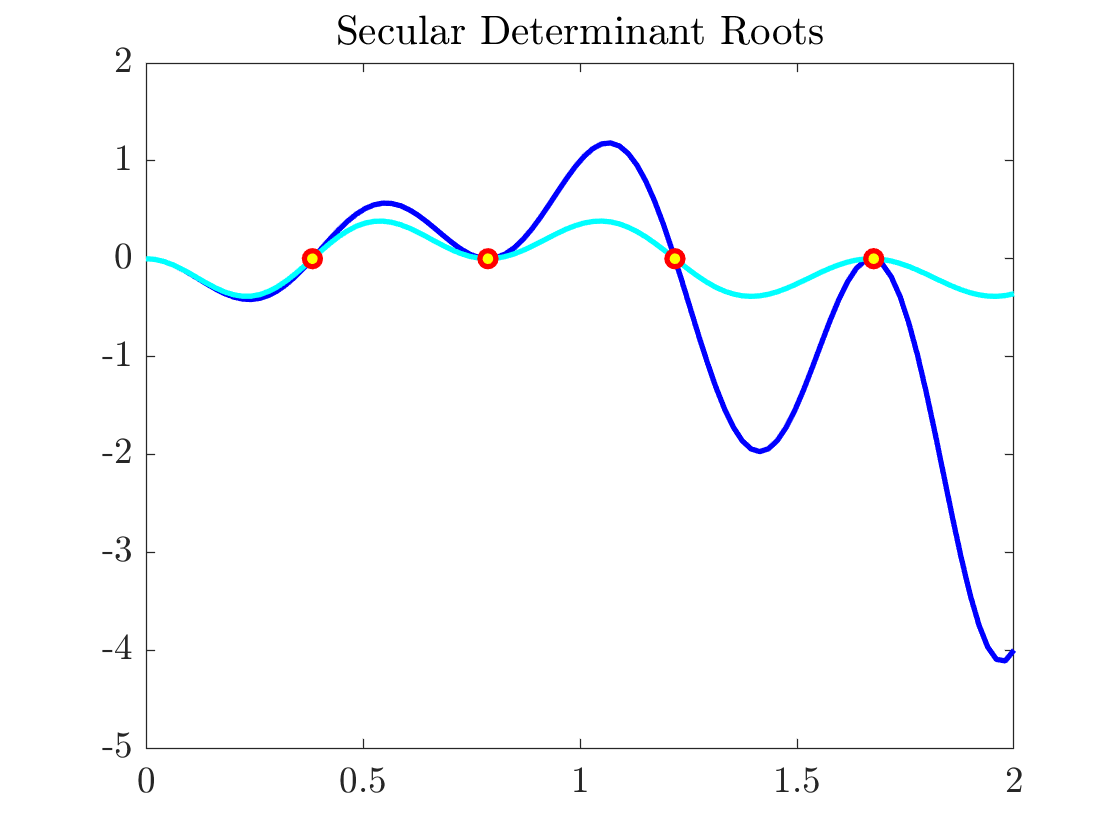

figure
plot(x,analyticFx,'color','b')
title('Secular Determinant Roots')
hold on
plot(x,Fx,'color','cyan')
hold on
plot(kstar,zeros(size(kstar)),'*','color','y')
hold on
plot(kstarA,zeros(size(kstarA)),'o','color','r')

## Compares secular determinant to Laplacian eigenvalue

Table of found lambda values. The column labels are shorthand for:

NSD: evals from the numerical SD

ASD: evals from the analytical SD

Cheb: evals from Chebyshev Laplacian

Uni: evals from uniform Laplacian

[~,lambda] = eigs(Phi,5);
lambda = uniquetol(lambda);
sqrt(lambda);
[~,lambdaU] = eigs(PhiU,5);
lambdaU = uniquetol(lambdaU);
lambdaU = -flip(lambdaU);
sqrt(lambdaU);

A = [lambdaNumerical'; lambdaAnalytic'; lambda'; lambdaU'];

T = array2table(A','VariableNames', ...
    {'NSD','ASD','Cheb','Uni'})

T = 4×4 table
      NSD        ASD       Cheb        Uni  
    _______    _______    _______    _______

    0.14703    0.14703    0.14703    0.18684
    0.62075    0.62075    0.62037    0.75596
     1.4853     1.4853     1.4853     1.7288
     2.8115     2.8115     2.7943     3.1307


Compare zeros of SD (represented on plot) to the sqrt of the evals. They should be the same!

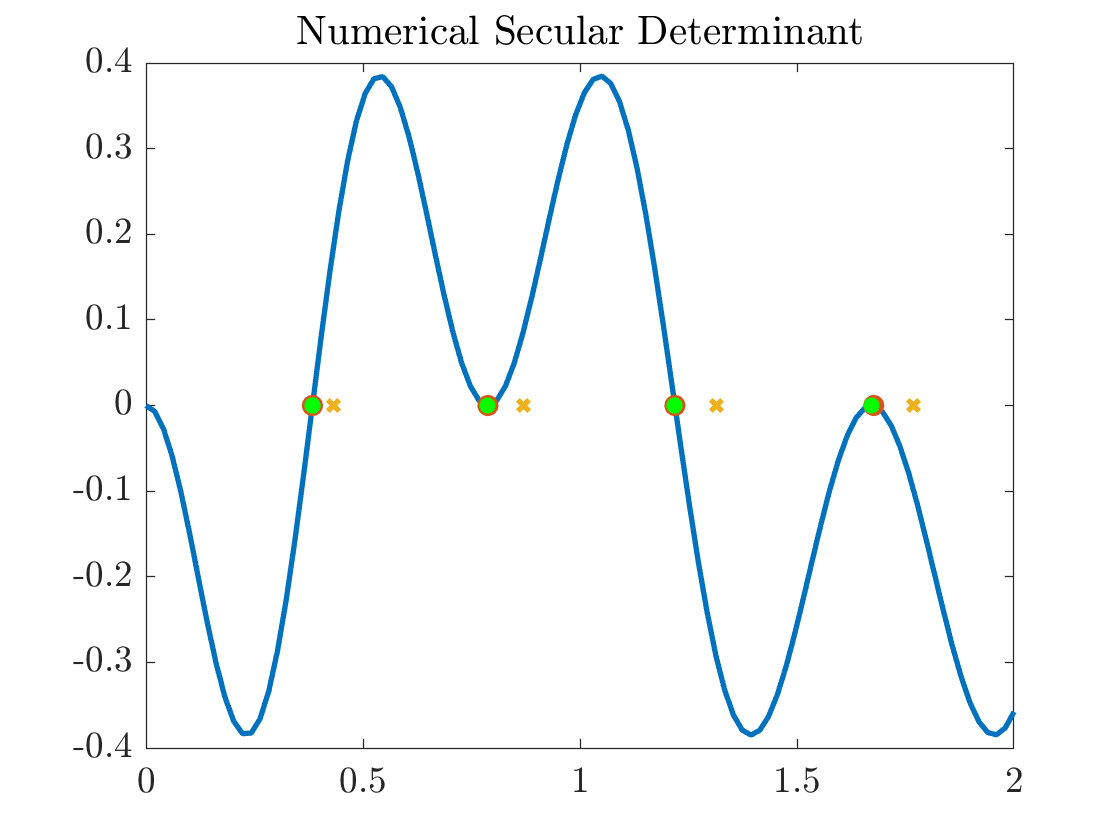

figure
plot(x,Fx)
title('Numerical Secular Determinant')
hold on
plot(kstar,zeros(size(kstar)),'o')
hold on
plot(sqrt(lambdaU),zeros(size(lambdaU)),'x')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')

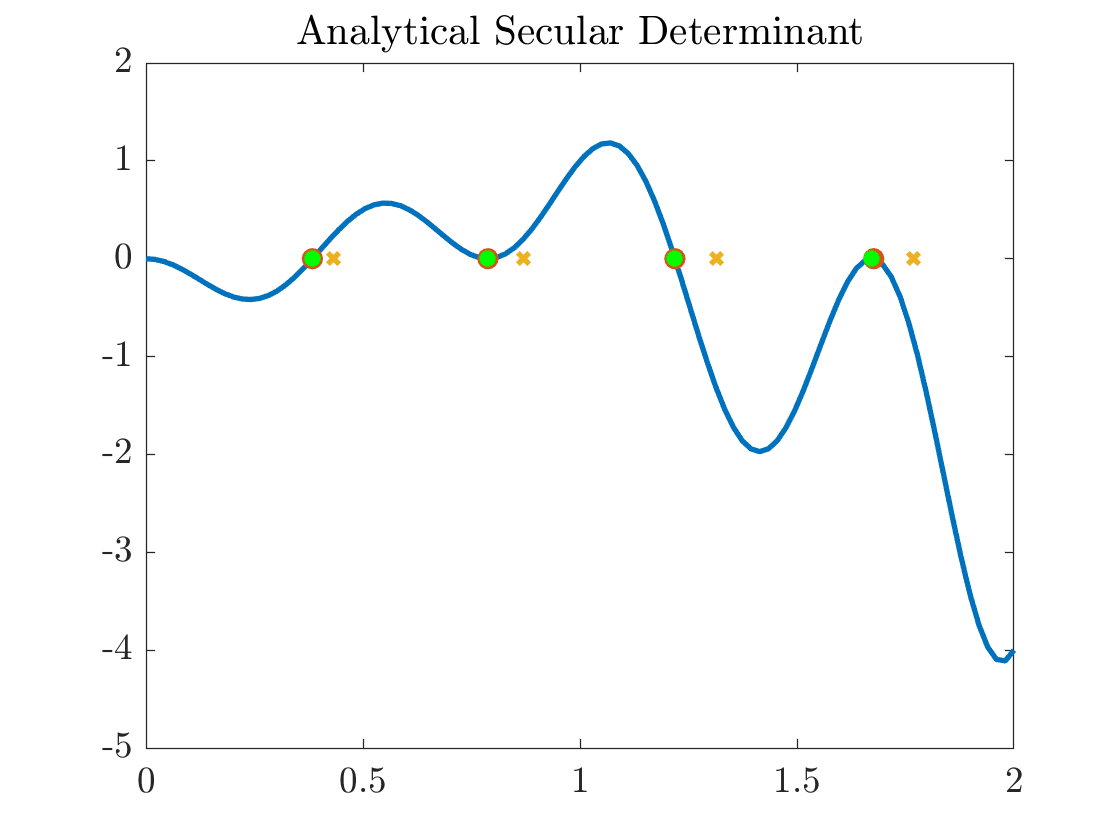



figure
plot(x,analyticFx)
title('Analytical Secular Determinant')
hold on
plot(kstarA,zeros(size(kstarA)),'o')
hold on
plot(sqrt(lambdaU),zeros(size(lambdaU)),'x')
hold on
plot(sqrt(lambda),zeros(size(lambda)),'*','color','g')